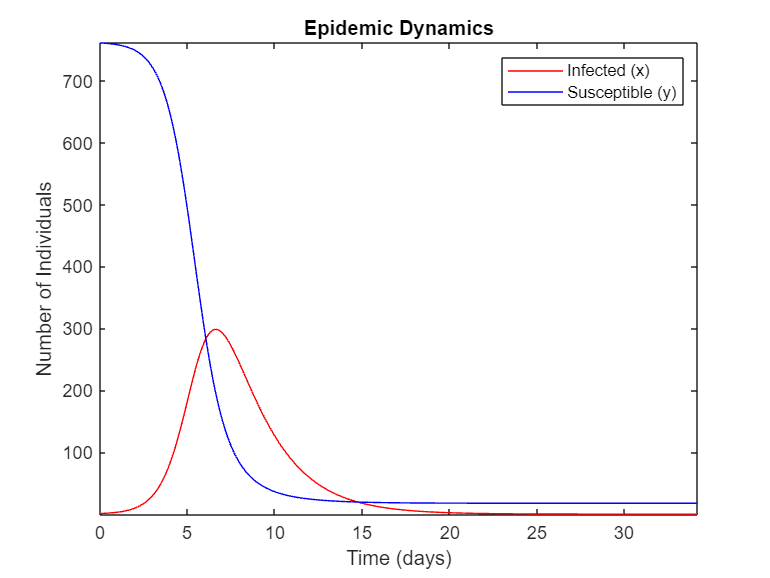

% Parameters
A = 2.18e-3; % Infection rate (per day)
B = 0.44;   % Removal rate (per day)
N = 762;    % Total population size
x0 = 1;     % Initial infected individuals
y0 = N - x0; % Initial susceptible individuals
t_end = 50; % End time (days)
dt = 0.1;   % Time step (days)

% Initialize variables
t = 0:dt:t_end;
x = zeros(size(t));
y = zeros(size(t));
z = zeros(size(t));
x(1) = x0;
y(1) = y0;
z(1) = 0;

% Euler's method
for i = 1:length(t)-1
    dx = A * x(i) * y(i) - B * x(i);
    dy = -A * x(i) * y(i);
    dz = B * x(i);
    
    x(i+1) = x(i) + dx * dt;
    y(i+1) = y(i) + dy * dt;
    z(i+1) = z(i) + dz * dt;
end

% Plotting
figure;
%subplot(2,1,1);
plot(t, x, 'r', t, y, 'b');
xlabel('Time (days)');
ylabel('Number of Individuals');
legend('Infected (x)', 'Susceptible (y)');
title('Epidemic Dynamics');
xlim([0 25]);

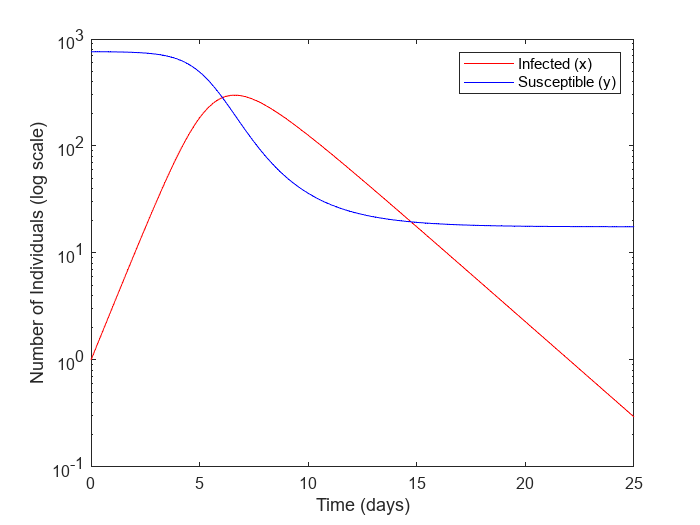


figure;
%subplot(2,1,2);
semilogy(t, x, 'r', t, y, 'b');
xlabel('Time (days)');
ylabel('Number of Individuals (log scale)');
legend('Infected (x)', 'Susceptible (y)');
xlim([0 25]);

% Finding the time when x reaches its maximum value
[max_x, idx] = max(x);
time_max_x = t(idx);
disp(['Time when x reaches maximum value: ', num2str(time_max_x), ' days']);

Time when x reaches maximum value: 6.6 days


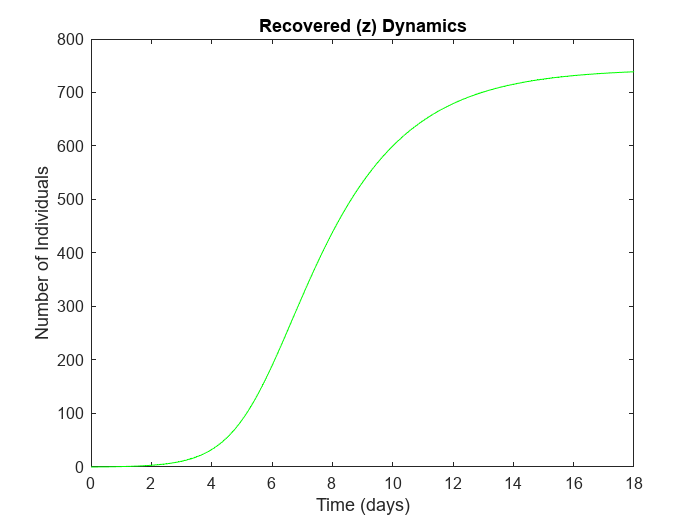


% C. Plot z along the vertical axis (with and without a logarithmic scale)
figure;

plot(t, z, 'g');
xlabel('Time (days)');
ylabel('Number of Individuals');
title('Recovered (z) Dynamics');
xlim([0 18]);

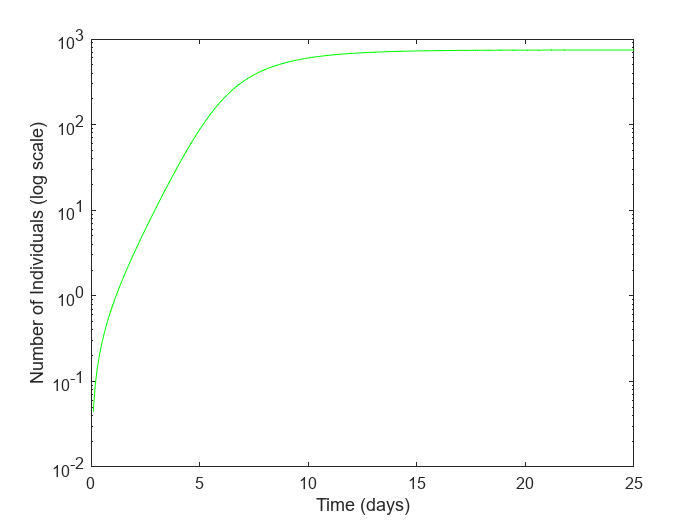

figure;
semilogy(t, z, 'g');
xlabel('Time (days)');
ylabel('Number of Individuals (log scale)');
xlim([0 25]);

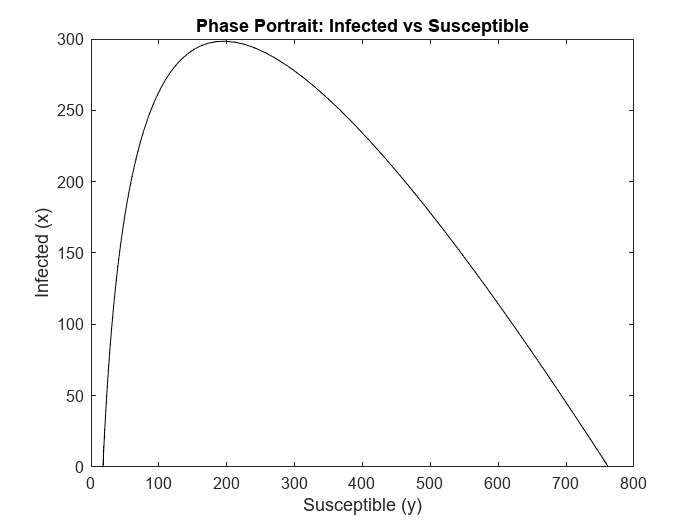

% D. Plot x along the vertical axis and y along the horizontal axis

figure;
plot(y, x, 'k');
xlabel('Susceptible (y)');
ylabel('Infected (x)');
title('Phase Portrait: Infected vs Susceptible');


% Compare with threshold values
rho = B / A; % Threshold value
R = A * y0 / B; % Reproduction number

disp(['Threshold value (rho): ', num2str(rho)]);

Threshold value (rho): 201.8349


disp(['Reproduction number (R): ', num2str(R)]);

Reproduction number (R): 3.7704



if R > 1 || y0 > rho
    disp('An epidemic breaks out.');
else
    disp('No epidemic occurs.');
end

An epidemic breaks out.


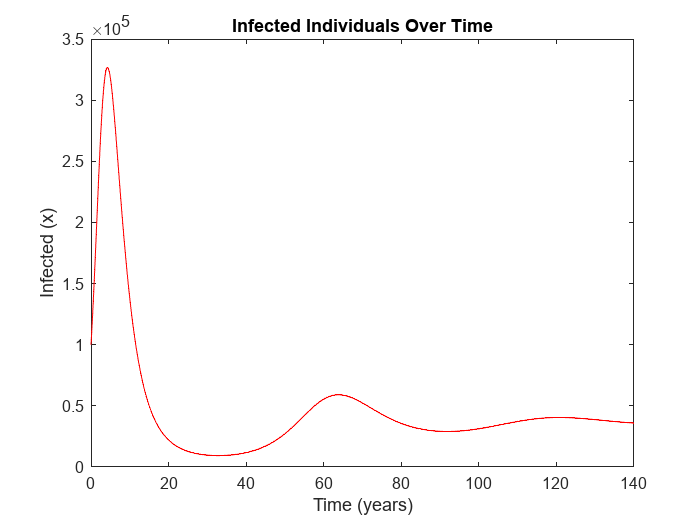


% Parameters
a = 0.02;       % Per capita death rate (year^-1)
b = 0.02;       % Per capita birth rate (year^-1)
A = 1e-6;       % Infection rate (year^-1)
B = 0.333;      % Removal rate (year^-1)
N = 1e6;        % Total population size
x0 = 1e5;       % Initial infected individuals
y0 = 9e5;       % Initial susceptible individuals
t_end = 140;     % End time (years)
dt = 1/365;     % Time step (1 day in years)

% Initialize variables
t = 0:dt:t_end;
x = zeros(size(t));
y = zeros(size(t));
z = zeros(size(t));
N_t = zeros(size(t));
x(1) = x0;
y(1) = y0;
z(1) = 0;
N_t(1) = N;

% Euler's method
for i = 1:length(t)-1
    dx = A * x(i) * y(i) - B * x(i) - a * x(i);
    dy = b * N_t(i) - A * x(i) * y(i) - a * y(i);
    dz = B * x(i) - a * z(i);
    dN = (b - a) * N_t(i);
    
    x(i+1) = x(i) + dx * dt;
    y(i+1) = y(i) + dy * dt;
    z(i+1) = z(i) + dz * dt;
    N_t(i+1) = N_t(i) + dN * dt;
end

% B. Plot x along the vertical axis and t (in years) along the horizontal axis
figure;
plot(t, x, 'r');
xlabel('Time (years)');
ylabel('Infected (x)');
title('Infected Individuals Over Time');

% Find peaks of x
[peak_values, peak_times] = findpeaks(x);
disp('Times when x reaches its peaks (years):');

Times when x reaches its peaks (years):


disp(peak_times);

        1549       23303       44056



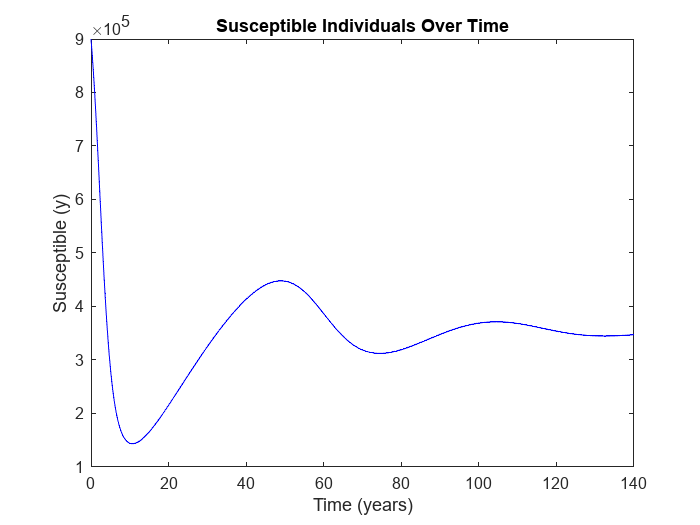


% C. Plot y and z along the vertical axis and t (in years) along the horizontal axis
figure;
%subplot(2,1,1);
plot(t, y, 'b');
xlabel('Time (years)');
ylabel('Susceptible (y)');
title('Susceptible Individuals Over Time');

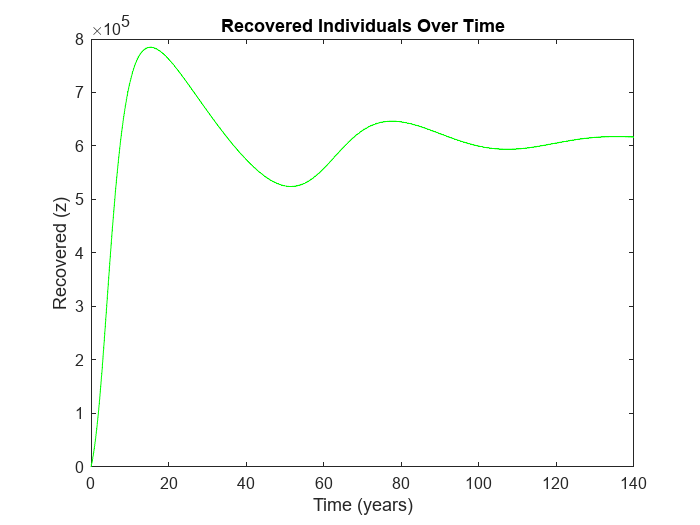

figure;
%subplot(2,1,2);
plot(t, z, 'g');
xlabel('Time (years)');
ylabel('Recovered (z)');
title('Recovered Individuals Over Time');